# Independent Component Analysis of whole brain using Aya's EEG dataset

clear;

if exist('H:\', 'dir')  % If H:\ exists, assume this is Computer 1
    input_path = 'H:\My Drive\Data\New Data\EEG epoched\';
    output_path = 'C:\Users\sinad\OneDrive - Georgia Institute of Technology\Dr. Sederberg MaTRIX Lab\temporal_criticality_of_latent_results';

elseif exist('G:\', 'dir')  % If G:\ exists, assume this is Computer 2
    input_path = 'G:\My Drive\Data\New Data\EEG epoched\';
    output_path = 'C:\Users\sdabiri\OneDrive - Georgia Institute of Technology\Dr. Sederberg MaTRIX Lab\temporal_criticality_of_latent_results';
else
    error('Unknown system: Cannot determine input and output paths.');
end

conditions = {'BLA','BLT', 'P1', 'P2', 'P3'}; %
subjects = {'BOS2'};%, 'BOS3', 'BOS5', 'BOS6', 'BOS7', 'BOS8', 'BOS9', 'BOS10', ...
    % 'BOS11', 'BOS12', 'BOS13', 'BOS15', 'BOS16', 'BOS17'

## Initialize structures for plotting

% We'll store PC results for each filtering type, condition, and channel
all_results = struct();

% Create a cell array to store all subject data for later combining
subject_data_cell = cell(length(subjects), 1); 

for subj_idx = 1:length(subjects)
    subject = subjects{subj_idx};
    all_results.(subject) = struct();
    all_results.(subject).unfiltered = struct();
    all_results.(subject).beta = struct();
    
    all_results.(subject).unfiltered.signal = [];
    all_results.(subject).unfiltered.normalized = [];
    all_results.(subject).unfiltered.icasig = [];
    all_results.(subject).unfiltered.A = [];
    all_results.(subject).unfiltered.W = [];
    all_results.(subject).beta.signal = [];
    all_results.(subject).beta.normalized = [];
    all_results.(subject).beta.icasig = [];
    all_results.(subject).beta.A = [];
    all_results.(subject).beta.W = [];    
end

    Using file: binepochs filtered ICArej BLAAvgBOS2.set


pop_loadset(): loading file G:\My Drive\Data\New Data\EEG epoched\BLA\binepochs filtered ICArej BLAAvgBOS2.set ...
Reading float file 'G:\My Drive\Data\New Data\EEG epoched\BLA\binepochs filtered ICArej BLAAvgBOS2.fdt'...
eeg_checkset: recomputing the ICA activation matrix ...


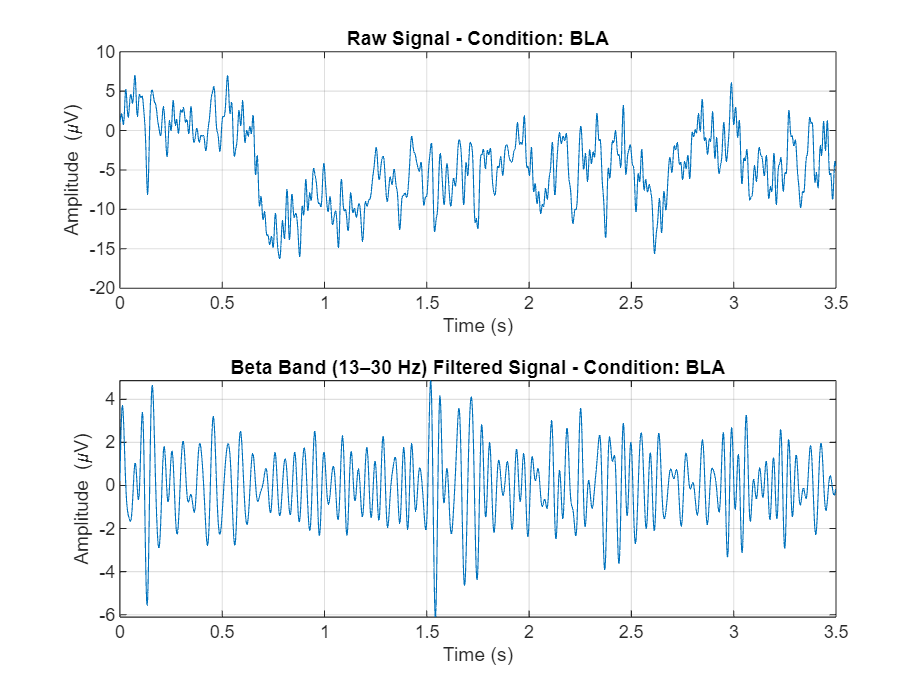

    Using file: binepochs filtered ICArej BLTAvgBOS2.set


pop_loadset(): loading file G:\My Drive\Data\New Data\EEG epoched\BLT\binepochs filtered ICArej BLTAvgBOS2.set ...
Reading float file 'G:\My Drive\Data\New Data\EEG epoched\BLT\binepochs filtered ICArej BLTAvgBOS2.fdt'...
eeg_checkset: recomputing the ICA activation matrix ...


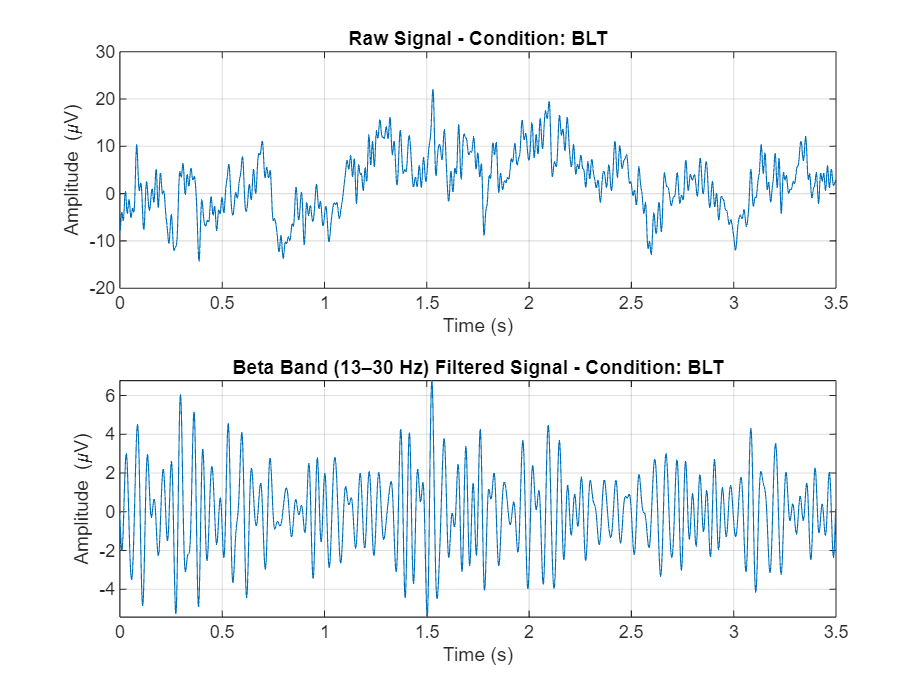

    Using file: binepochs filtered ICArej P1AvgBOS2.set


pop_loadset(): loading file G:\My Drive\Data\New Data\EEG epoched\P1\binepochs filtered ICArej P1AvgBOS2.set ...
Reading float file 'G:\My Drive\Data\New Data\EEG epoched\P1\binepochs filtered ICArej P1AvgBOS2.fdt'...
eeg_checkset: recomputing the ICA activation matrix ...


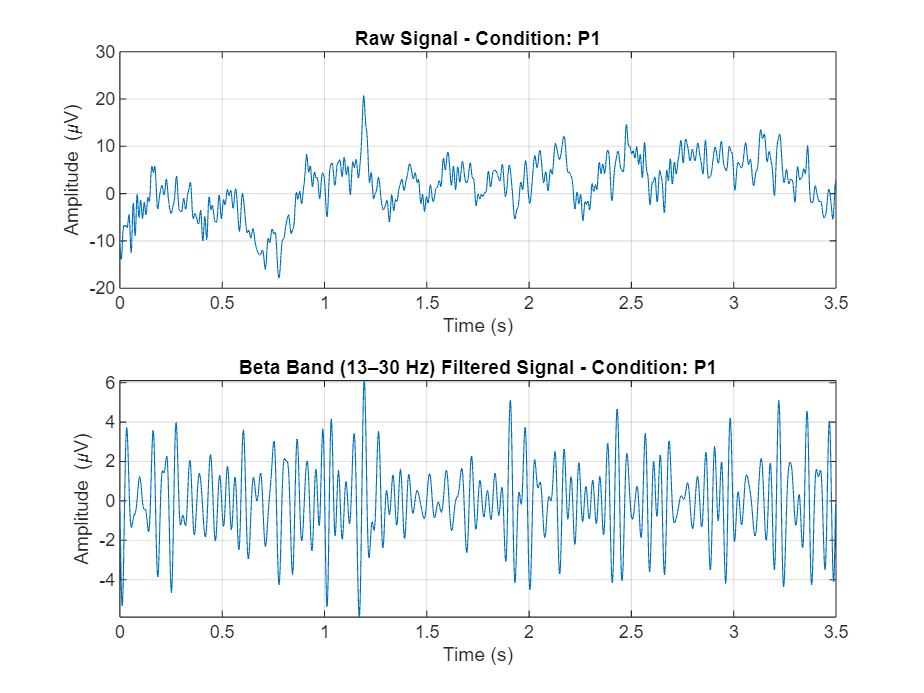

    Using file: binepochs filtered ICArej P2AvgBOS2.set


pop_loadset(): loading file G:\My Drive\Data\New Data\EEG epoched\P2\binepochs filtered ICArej P2AvgBOS2.set ...
Reading float file 'G:\My Drive\Data\New Data\EEG epoched\P2\binepochs filtered ICArej P2AvgBOS2.fdt'...
eeg_checkset: recomputing the ICA activation matrix ...


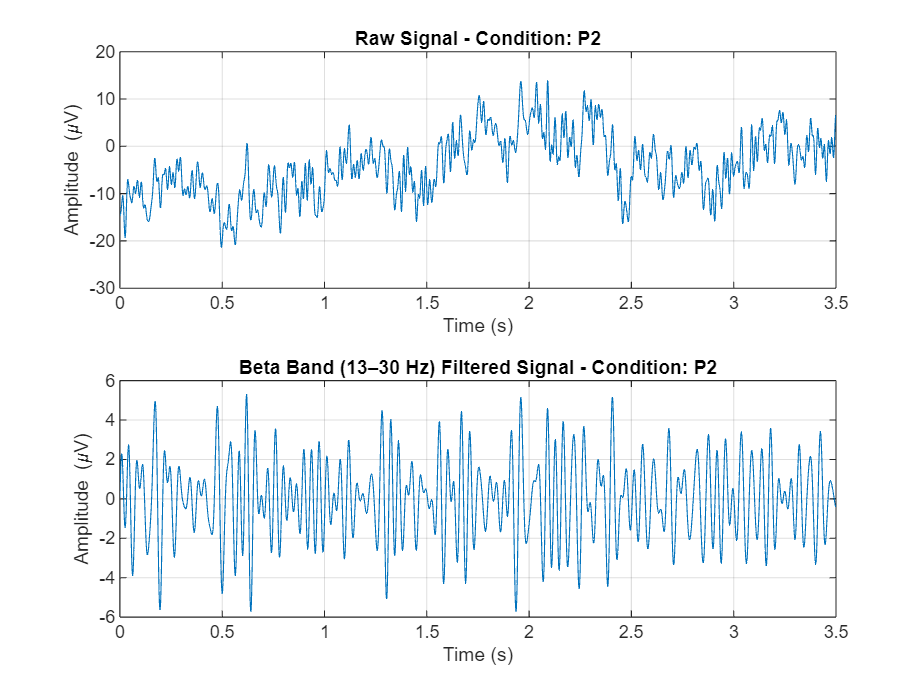

    Using file: binepochs filtered ICArej P3AvgBOS2.set


pop_loadset(): loading file G:\My Drive\Data\New Data\EEG epoched\P3\binepochs filtered ICArej P3AvgBOS2.set ...
Reading float file 'G:\My Drive\Data\New Data\EEG epoched\P3\binepochs filtered ICArej P3AvgBOS2.fdt'...
eeg_checkset: recomputing the ICA activation matrix ...


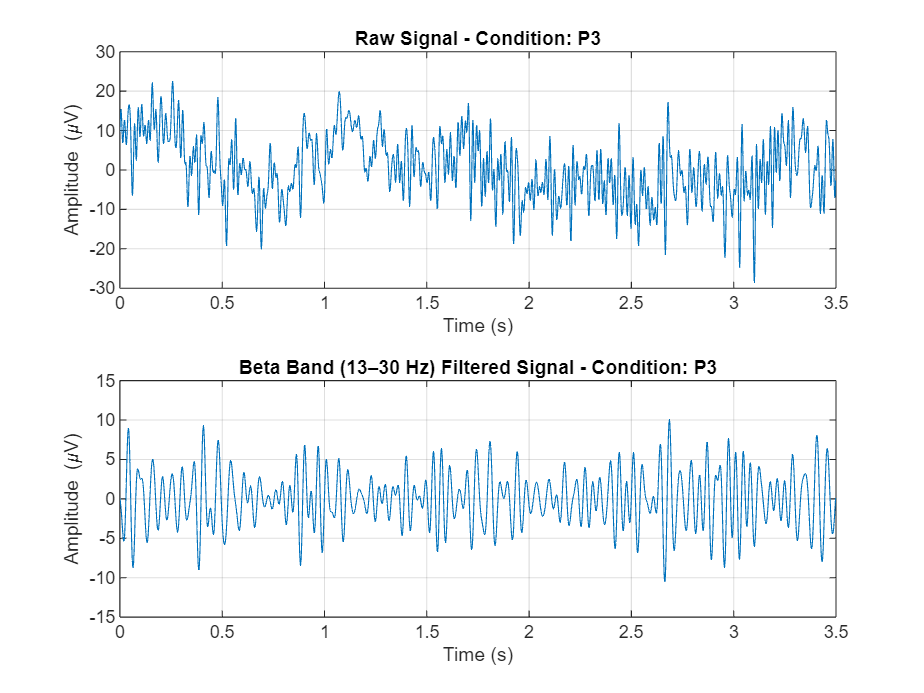

Dot indexing is not supported for variables of this type.

Error in eeg_eval (line 156)
                fprintf('Processing group dataset %d of %d named: %s ****************\n', i, length(EEG), EEG(i).setname);

Error in pop_runica (line 315)
   

% 1- Concatanate all 5 conditions per subject 
% - 1.1 Filter for beta band
% - 1.2 Z-score normalize per channel

num_ch= 32; 
num_time_samples = 1792;
num_trials = 60; 
num_conditions = length(conditions);
signal_giant = zeros(num_ch,  num_time_samples * num_trials * num_conditions);
beta_signal_giant = zeros(num_ch,  num_time_samples * num_trials * num_conditions);
col_start = 1;
% Loop over each subject's dataset
for j = 1:length(subjects)
    % Loop over each condition
    for i = 1:length(conditions)
        condition = conditions{i};
        input_path_condition = fullfile(input_path, condition);
        output_path_condition = fullfile(output_path, condition);
        if strcmp(condition, 'P2')
            excel_file_path = fullfile(input_path,'Indexes for P2.xlsx');
        elseif strcmp(condition, 'P3')
            excel_file_path = fullfile(input_path,'Indexes for P3.xlsx');
        else
            excel_file_path = '';
        end
    
        if ~exist(output_path_condition, 'dir')
            mkdir(output_path_condition);
        end
        
        % Get all .set files in the directory
        set_files = dir(fullfile(input_path_condition, '*.set'));
        file_idx = find_subject_file(set_files, subject);
        file_path = fullfile(input_path_condition, set_files(file_idx).name);
        disp(['    Using file: ', set_files(file_idx).name]);
        EEG = pop_loadset(file_path);
        
        % Extract relevant parameters
        fs = EEG.srate; % Sampling rate
        % time_vector = linspace(-0.5, 3, size(EEG.data, 2)); % Time axis (-500ms to 3000ms)
    
        % Select odd or even epochs based on condition
        if strcmp(condition, 'BLA') || strcmp(condition, 'P1') || strcmp(condition, 'P2') || strcmp(condition, 'P3')
            epoch_trials = 1:2:EEG.trials; % Odd epochs
        elseif strcmp(condition, 'BLT')
            epoch_trials = 2:2:EEG.trials; % Even epochs
        else
            error('Condition not recognized. Please specify "BLA" or "BLT".');
        end
    
        num_trials = length(epoch_trials);
        data = EEG.data(:, :, epoch_trials);
        
        % Bandpass filter beta band (13-30 Hz)
        beta_band = [13 30];
        beta_signal = zeros(size(data)); % Preallocate
        for epoch = 1:size(data, 3)
            beta_signal(:,:,epoch) = bandpass(data(:,:,epoch)', beta_band, fs)';
        end
        
        % Plot one trial (e.g., the first trial) from one channel (e.g., channel 1) for visualization
        trial_to_plot = 1;
        channel_to_plot = 18;
        
        raw_signal = squeeze(data(channel_to_plot, :, trial_to_plot));
        filtered_signal = squeeze(beta_signal(channel_to_plot, :, trial_to_plot));
        time_vector = (0:length(raw_signal)-1) / fs;  % assuming time starts at 0
        
        figure('Name', ['Condition: ' condition], 'NumberTitle', 'off');
        subplot(2,1,1);
        plot(time_vector, raw_signal);
        title(['Raw Signal - Condition: ' condition]);
        xlabel('Time (s)');
        ylabel('Amplitude (\muV)');
        grid on;
        
        subplot(2,1,2);
        plot(time_vector, filtered_signal);
        title(['Beta Band (13–30 Hz) Filtered Signal - Condition: ' condition]);
        xlabel('Time (s)');
        ylabel('Amplitude (\muV)');
        grid on;

        signal_reshape = reshape(data, num_ch,num_time_samples*num_trials );
        beta_signal_reshape = reshape(beta_signal, num_ch,num_time_samples*num_trials );
        signal_giant(:,col_start:num_time_samples *num_trials*i) = signal_reshape;
        beta_signal_giant(:,col_start:num_time_samples *num_trials*i) = beta_signal_reshape;
        col_start = 1+num_time_samples *num_trials*i;
    end
    all_results.(subject).unfiltered.signal = signal_giant;
    all_results.(subject).beta.signal = beta_signal_giant;

    % z-score normalize per channel
    all_results.(subject).unfiltered.normalized = zscore(all_results.(subject).unfiltered.signal,0,1);
    all_results.(subject).beta.normalized = zscore(all_results.(subject).beta.signal,0,1);

    % Perform ICA
    icasig = pop_runica(all_results.(subject).unfiltered.normalized, 'extended', 1, 'interupt','on');
    icasig_beta = pop_runica(all_results.(subject).beta.normalized, 'extended', 1, 'interupt','on');

    all_results.(subject).unfiltered.icasig = icasig;

    all_results.(subject).beta.icasig = icasig_beta;
   

end

% plotting the ICs
pop_topoplot(EEG, 0, 1:28, 'Title for ICs', [5 6], 0, 'electrodes', 'on');


% % Project 4D data back into IC space: This gives you the IC activations as a 4D tensor, preserving trial and condition structure.
% X_2D = reshape(X, ch, []);
% IC_activations = W * X_2D;  % W is ICA unmixing matrix
% IC_tensor = reshape(IC_activations, size(W,1), time, trials, conds);


## Helper function to find the file for a specific subject

function file_idx = find_subject_file(set_files, subject_id)
    file_idx = 0;
    for i = 1:length(set_files)
        filename = set_files(i).name;
        % Check if the subject ID (e.g., "BOS2") is part of the filename.
        % This is a more robust check than relying on specific parts or delimiters.
        if contains(filename, subject_id)
            file_idx = i;
            return; % Return as soon as a match is found
        end
    end
    % If loop completes, no match was found, file_idx remains 0.
end